% 1. Create the simulation name and the folder to save all simulated
% samples and parameters

% Give this simulation a name
SimulationName='Simulation_AfterRivisingFunctions_20231208';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/';
% Create the simulation folder
cd(savefolder)
mkdir(SimulationName)

% Go to the simulation folder
filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/Simulation_AfterRivisingFunctions_20231208/'

cd(filepath)

% Make the folder to save simulated samples later
mkdir('Simulated_data_pooled')

% 2. adjust the IRF based on delta peak time and save the IRF
% IRF file: probability density distribution in the format of a vector with 256 numbers corresponding to 256 time channels, and the numbers add up to 1.

% Load delta peak time (dpt) from fitting of the experimental FLIM_AKAR
% imaging data to adjust the IRF for fitting
load("AKAR_baseline_fitting_parameters.mat")
dpt = mean(dpt_all(1:10)) % Use the mean of delta peak time from 10 fitting from baseline of the experimental data

% Adjust IRF by dpt
PrfName_original = 'prf_InsightBottomGreen_20231017.mat'; % This is the original collected IRF file

load(PrfName_original) % Load the original prf file
x = (1:1:256)*(12.5/256); % Spreading the x axis (256 time channels) over 12.5ns
prf_interp1=interp1(x,prf,x+dpt,'linear'); % Adjust the prf based on delta peak time
prf_interp1(isnan(prf_interp1)) = 0; % Make the nan values to 0 after interpolation
prf = prf_interp1; % IRF variable has to be saved under the name prf

PrfName = 'Prf_interp1.mat' % New file name of the prf file

PrfName = 'Prf_interp1.mat'

save(PrfName, 'prf') % Give the prf file name, inside the prf file the prf file variable has to be saved as 'prf';

% 3. Load the fitting results from autofluorescence fitting.
% The file includes:
% a. autofluorescence distribution 'autofluo_corrrected'
% b. background term 'autofluo_bkgrd' from autofluorescence fitting that is used as imaging
% background in the simulation
% c. mean photon number for the autofluorescence photons
% 'AF_mean_corrected'
load('Autofluo_fitting_parameters')

% 4. Define the double exponential decay parameters and other parameters in
% the simulation

p1_samples=0.4:0.01:0.6; % simulate the p1 range
tau1=2.14; % tau1 
tau2=0.69; % tau2

afterpulse_ratio=0.0032; % Afterpulse ratio experimentally determined as 0.32% of the fluorescence signal

SS_samples=100000:50000:1000000; % simulated sample size range.

% 5. This is the content of the script for batch processing.
% use batch function for parallel computing of simulation

    p1=p1_samples(i); % Define p1
    p2=1-p1;
    n_sensor_simulated = {}; % Simulated histogram vector will be saved in this cell variable; simulated data of each sample size condition will be saved as one cell
    PopulationName=[SimulationName,'_FLP_population_',num2str(p1),'.mat']; % Define double exponential population name
    GenPop512_FLIM_v2(1000000, p1, p2, tau1, tau2, PopulationName);  % Generate the double exponential population
    parfor j=1:length(SS_samples)
        rng('shuffle','twister') % Shuffle the random number generator
        SS=SS_samples(j); % Define the sensor sample size
        n_all = zeros(500, 256); % For each sensor sample size condition, simulated data will be saved as row vectors in 'n_all' varible 
        for k=1:500 % Simulating 500 times
            [n1, n2, n] = FLIMsim512_FLIM_v2(SS,PrfName, PopulationName); % Simulation with corresponding sample size (SS), IRF (PrfName), and population (PopulationName)
            n_all(k, :) = n; % Save simulated data into n_all
        end
        n_sensor_simulated{j} = n_all; % Simulated data under each sample size condition is saved as one cell in 'n_sensor_simulated'
    end
    
    % Save the simulated data under each p1 condition as one file
    simulated_name = ['Simulated_data_pooled/', num2str(p1), '_sensor.mat'];
    save(simulated_name, 'n_sensor_simulated')


% 6. create the batch processing script, copy and paste the script above into the script and save it under the root folder of the simulation
edit Simulation_batch_20231208

% 7. call the local cluster
c=parcluster()

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: pingchuans-mbp
                NumWorkers: 21
                NumThreads: 1

        JobStorageLocation: /Users/pingchuanma/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2022a
   RequiresOnlineLicensing: false

    

% 8. batch processing of simulation, each p1 condition runs on one worker.
for i=1:length(p1_samples) % for each p1 value, run the script in parallel
    batch('Simulation_batch_20231208')
end

ans = 

 Job

    Properties: 

                   ID: 2
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 12-Dec-2023 09:57:46
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

% 9. the script for batch processing of simulation of autofluorescence


    SS=SS_samples(j); % Generate a set of simulated autofluorescence for each sensor sample size condition
    n_auto_all = zeros(500, 256); % Simulated data will be saved as a row vector in 'n_auto_all'
    for i=1:500 % Simulating 500 times
        rng('shuffle','twister') % Shuffle the random number generator
        AF=(randi(round(AF_mean_corrected*0.1)))+round(AF_mean_corrected*0.95); % Introduce 10% of fluctuation of the autofluorescence photon number
        [n_auto] = AutoFluo_sim_v2(autofluo_corrected, AF); % Simulation of autofluorescence based on autofluorescence distribution 'autofluo_corrected' and autofluorescence photon number 'AF'
        n_auto_all(i, :) = n_auto; % Save simulated data as a row vector in 'n_auto_all'
    end
    % Save the simulated data under each photon number condition as one file
    autoF_save_name = ['autoF_', num2str(SS), '.mat'];
    save(autoF_save_name, 'n_auto_all')


% 10. create the batch processing script for simulationg autofluorescence, copy and paste the script above into the script and save it under the root folder of the simulation

edit Autofluo_corrected_simulation_20231201

% 11. call the local cluster
c=parcluster()

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: Pingchuans-MBP
                NumWorkers: 21
                NumThreads: 1

        JobStorageLocation: /Users/pingchuanma/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2022a
   RequiresOnlineLicensing: false

    

% 12. batch processing of simulation of corrected autofluorescence
for j=1:length(SS_samples)
    batch('Autofluo_corrected_simulation_20231201','pool',4)
end

ans = 

 Job

    Properties: 

                   ID: 1
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 11-Dec-2023 22:50:59
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 2
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 11-Dec-2023 22:51:16
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 3
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 11-Dec-2023 22:51:41
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 4
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 11-Dec-2023 22:52:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

% 13.  This is to create the distribution of background
bkgrd_AP_distribution = zeros(1, 256) + 1/251; 
bkgrd_AP_distribution([1,2,3,4,256]) = 0; % Probability density distribution for background: background evenly distributed over time, but channel 1-4 and 256 as 0;
bkgrd_AP_sum = round(autofluo_bkgrd*251); % background total number

% 14. The script for batch processing of simulation of background

    SS=SS_samples(j); % Generate a set of simulated autofluorescence for each sensor sample size condition
    n_bkgrd_all = zeros(500, 256) % Simulated data will be saved as a row vector in 'n_bkgrd_all'
    for i=1:500
        rng('shuffle','twister')
        Bkgrd_AP=(randi(round(bkgrd_AP_sum*0.1)))+round(bkgrd_AP_sum*0.95); % Introduce 10% of fluctuation of the autofluorescence photon number
        Bkgrd_SensorAP = Bkgrd_AP + round(SS*afterpulse_ratio); % Adding afterpulse to the background based on the sample size (SS) and the afterpulse ratio (afterpulse_ratio)
        [n_bkgrd] = AutoFluo_sim_v2(bkgrd_AP_distribution, Bkgrd_SensorAP); % Simulation of background and afterpulse based on background distribution 'bkgrd_AP_distribution' and background and afterpulse photon number 'Bkgrd_SensorAP'
        n_bkgrd_all(i, :) = n_bkgrd; % Save simulated data as a row vector in 'n_bkgrd_all'
    end
 % Save the simulated data under each photon number condition as one file
    bkgrd_save_name = ['Simulated_data/bkgrd_AP_', num2str(SS), '.mat'];
    save(bkgrd_save_name, 'n_bkgrd_all')

% 15. create the folder and script for bactch processin of simulation of background
% and the afterpulse of the sensor fluorescence

edit Bkgrd_AP_simulation_20231201.m

% 16. call the local cluster
c=parcluster()

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: Pingchuans-MBP
                NumWorkers: 21
                NumThreads: 1

        JobStorageLocation: /Users/pingchuanma/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2022a
   RequiresOnlineLicensing: false

    

ans = 

 Job

    Properties: 

                   ID: 5
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 11-Dec-2023 23:02:52
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 6
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 11-Dec-2023 23:03:04
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 7
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 11-Dec-2023 23:03:27
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 8
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 11-Dec-2023 23:04:03
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

Error using load
Unable to find file or directory 'Simulated_data/0.5_sensor.mat'.

Unrecognized function or variable 'p1_samples'.

Error using load
Unable to find file or directory 'Simulated_data/bkgrd_AP_300000.mat'.

savename_postfix = 'Results_20231210_3_'

h =   HeatmapChart with properties:

        XData: {21×1 cell}
        YData: {15×1 cell}
    ColorData: [15×21 double]

  Show all properties


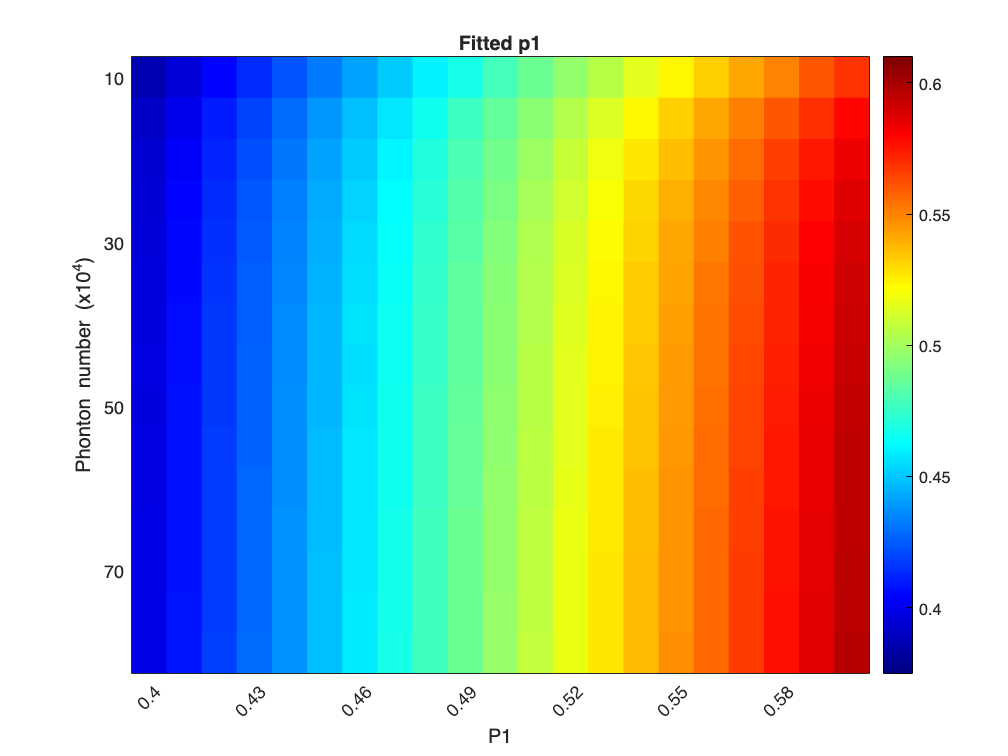

h =   HeatmapChart with properties:

        XData: {21×1 cell}
        YData: {15×1 cell}
    ColorData: [15×21 double]

  Show all properties


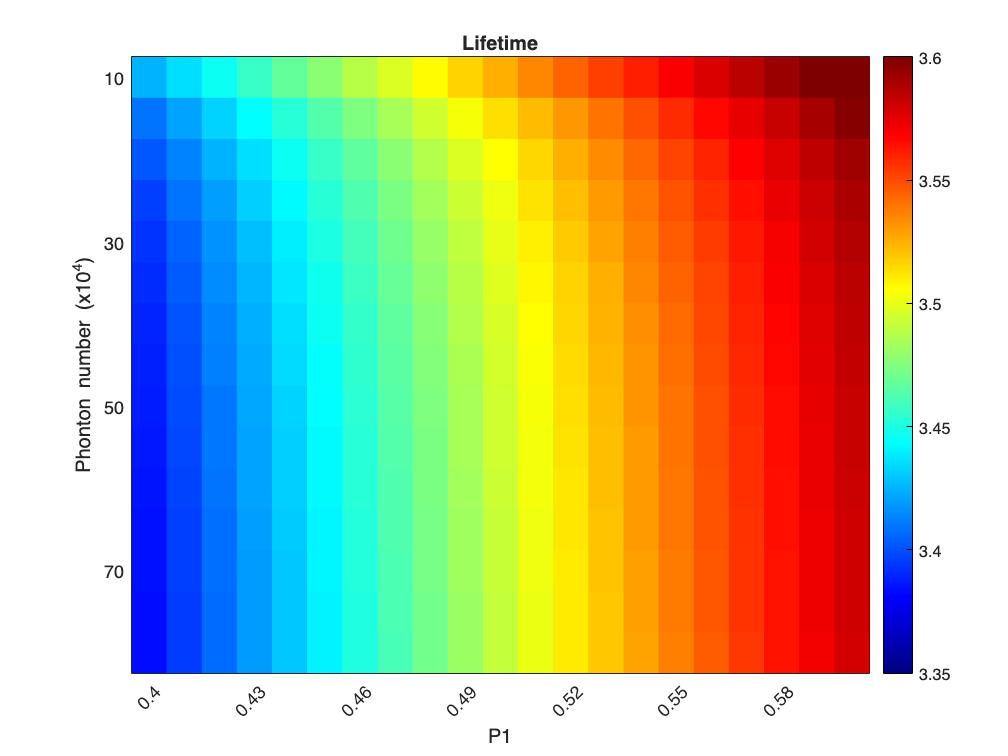

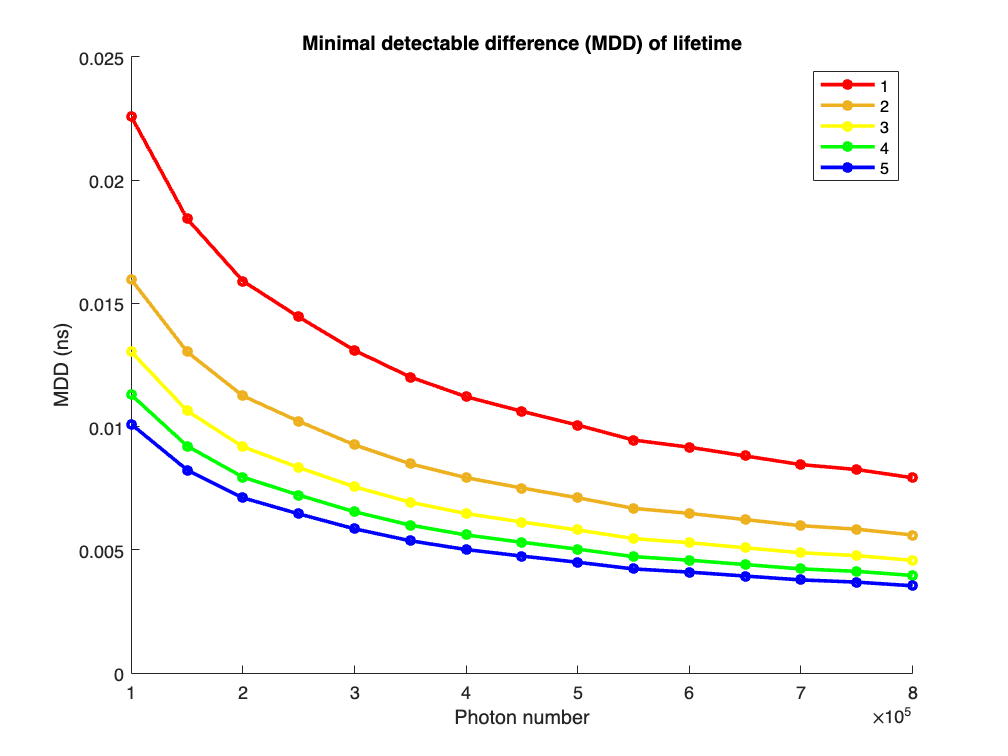

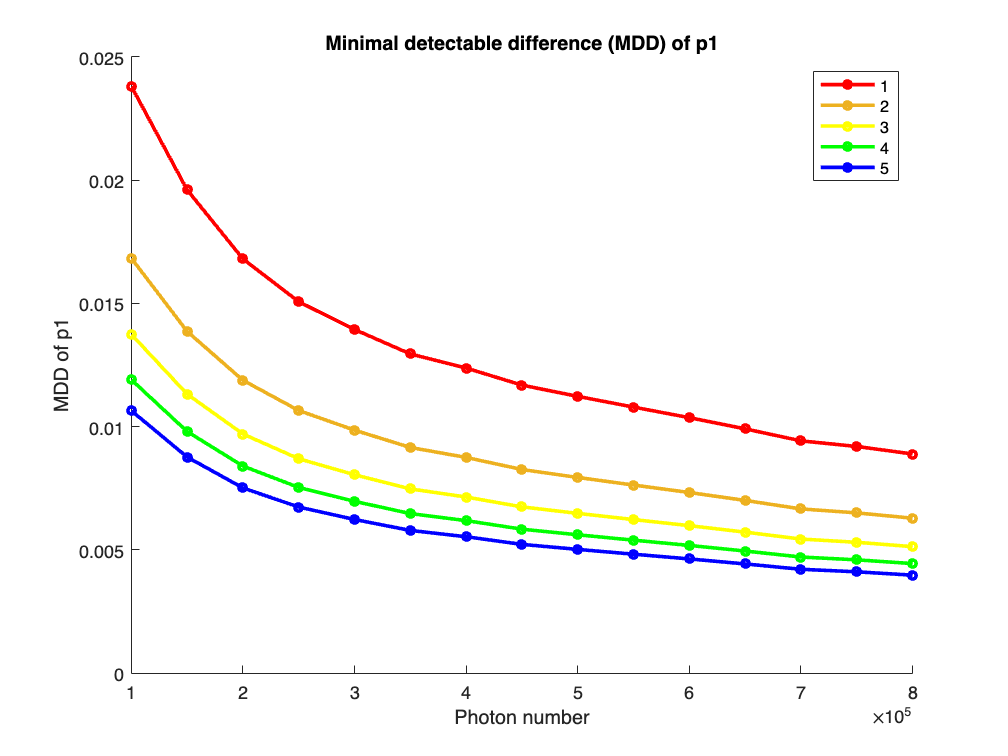

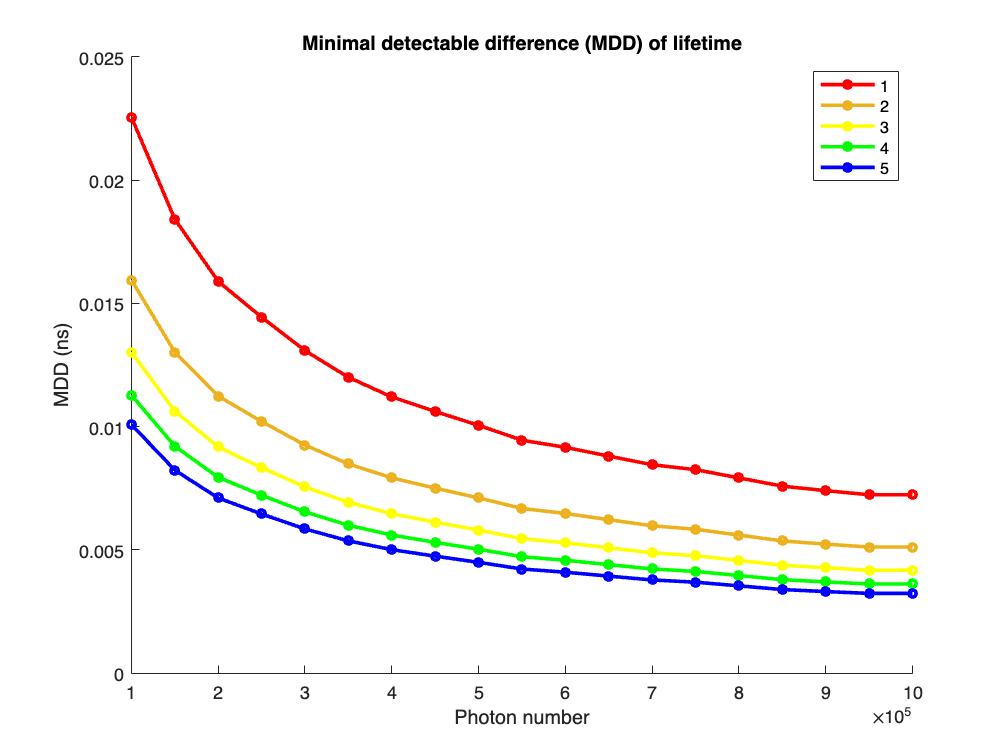

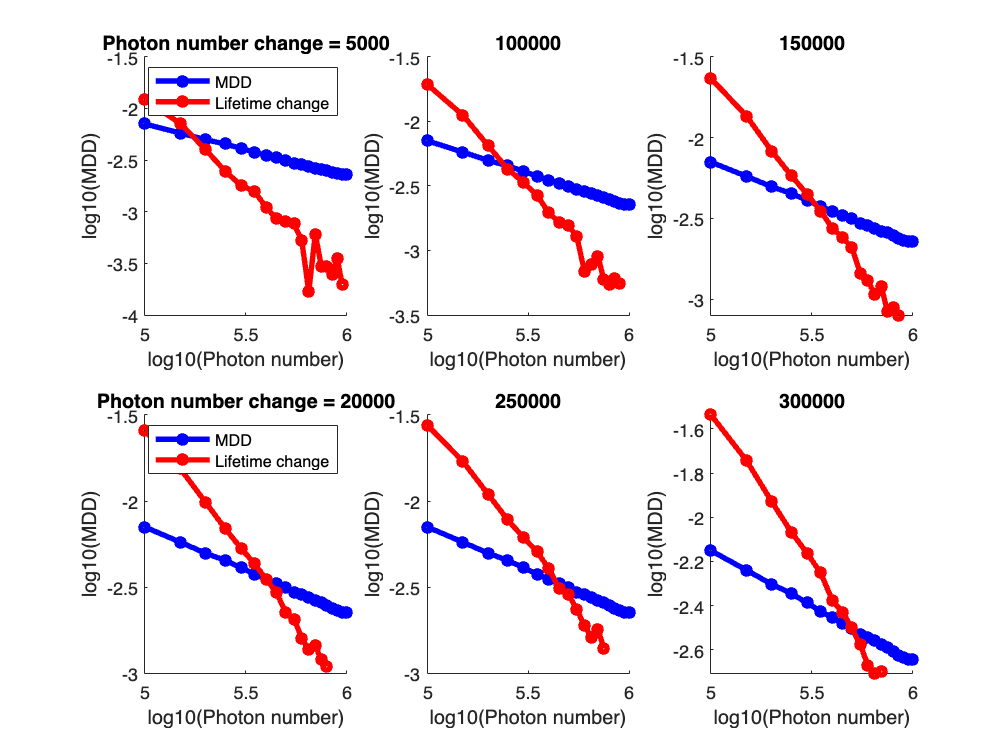

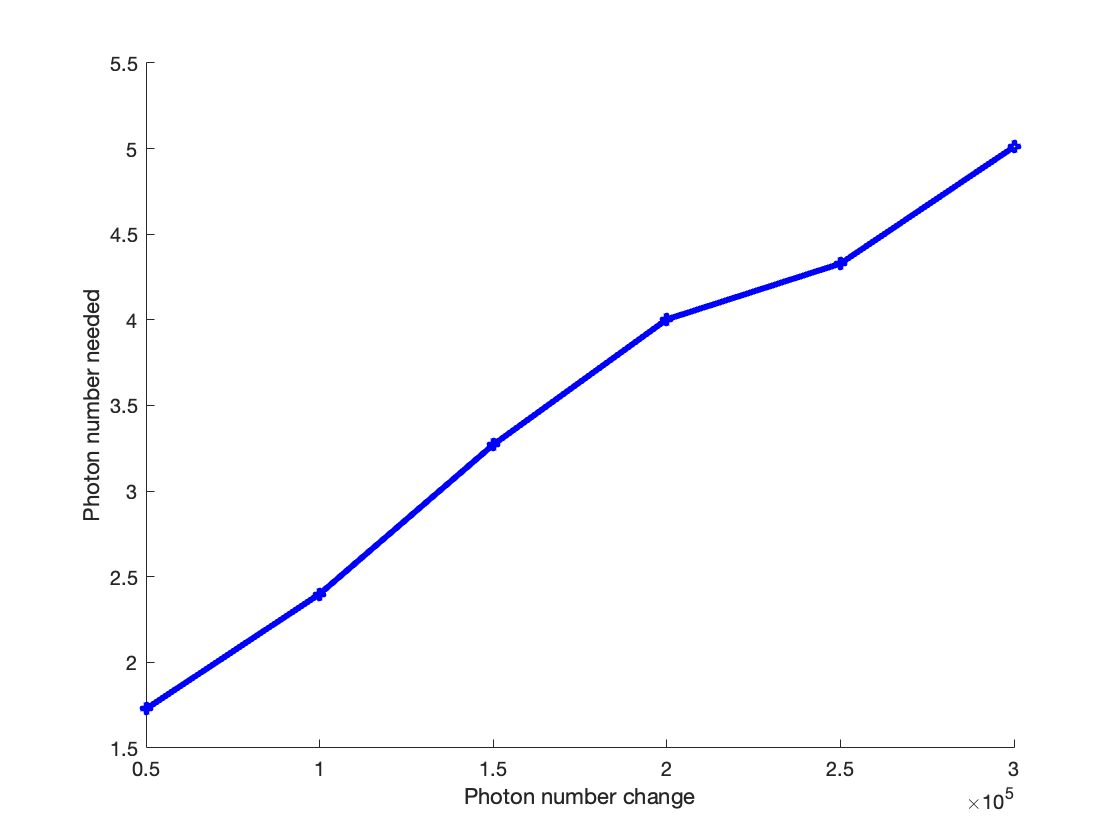

% 17. batch processing of simulation of background
for j=1:length(SS_samples)
    batch('Bkgrd_AP_simulation_20231201','pool',4)
end